## Podobieństwo sygnałów

Materiał pochodzi z bloga ont: [https://matlablog.ont.com.pl/matlab-film-jak-obliczyc-korelacje/?fbclid=IwAR3IsgaZuLQv55SEZDdvWl_LaYTRbUrDwJBUIgbI2mW7wsHKFnaOFdm-Ra8](https://matlablog.ont.com.pl/matlab-film-jak-obliczyc-korelacje/?fbclid=IwAR3IsgaZuLQv55SEZDdvWl_LaYTRbUrDwJBUIgbI2mW7wsHKFnaOFdm-Ra8)

clear all; close all; clc
open my_figure.m
load 2022_garmin_data


#### Wykresy danych

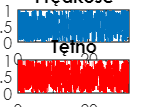

HR = rand(704,1);
V = rand(704,1);
%HR = -HR
figure; subplot(211); plot(t, V, 'LineWidth', 2); 
my_figure('', 'V [km/h]', 'Prędkość'); grid on;
subplot(212); plot(t, HR, 'r', 'LineWidth', 2);
my_figure('czas [min]', 'HR [bpm]', 'Tętno'); grid on;

#### Współczynnik KOWARIANCJI


$$\textrm{cov}\left\lbrack x\left(t\right),y\left(t\right)\right\rbrack =\lim_{T\longrightarrow \infty } \frac{1}{T}\int_0^T \left\lbrack x\left(t\right)-\mu_x \right\rbrack \cdot \left\lbrack y\left(t\right)-\mu_y \right\rbrack \cdot \textrm{dt}$$


Cechy współczynnika kowariancji: przyjmuje wartości rzeczywiste: ujemne- ujemna korelacja, dodatnie- dodatnia korelacja, 0- brak korelacji

- dla dwóch sygnałów x i y- granica z całki oznaczonej z iloczynu dwóch badanych sygnałów, od każdego z badanych sygnałów odejmowana jest średnia odpowiedniego sygnału

- dodatnia korelacja- sygnały są w fazie -> wzrost jednego sygnału powoduje wzrost drugiego sygnału

- ujemna korelacja- sygnały są w przeciwfazie-> wzrost jednego sygnału powoduje spadek drugiego sygnału

- Matlab posiada wbudowaną funkcję do obliczenia współczynnika kowariancji- funkcja *cov-* w funkcji tej całka zamieniona jest na sumę, gdzie od wartości sygnałów odejmowane są ich średnie wartości. Funkcja ta jest normowana przez N-1:

współczynnik kowariancji obliczony wg wprowadzonego wzoru cov[x(t), y(t)]

wsp_cov1 = dt * sum((V-mean(V)) .* (HR-mean(HR))) / to %

wsp_cov1 = 0.0027

współczynnik kowariancji z funkcji Matlaba cov(A,B)- obliczony ręcznie

wsp_cov2 = sum((V-mean(V)) .* (HR-mean(HR))) / (N-1)

wsp_cov2 = 0.0027

Funkcja Matlaba do obliczenia współczynnika kowariancji

m_cov = cov(V,HR)

m_cov =     0.0819    0.0027
    0.0027    0.0797


z współczynnika kowariancji obliczonego przez funkcję w Matlabie cov(A,B) otrzymujemy macierz kowariancji. Na głównej przekątnej- wariancje sygnałów. Na pozostałych przekątnych kowariancja. Wartość kowariancji jest zbieżna z wartościami kowariancji obliczonymi i zapisanymi pod zmiennymi wsp_cov1 i wsp_cov2.

Funkcja do obliczania współczynnika kowariancji ma przewagę nad pozostałymi prezentowanymi rozwiązaniami, poniewaz pozwala na obliczenie współczynnika dla więcej niż jednej pary zmiennych.

Współczynnik kowariancji podaje wartość nieunormowaną (z zakresu liczb rzeczywistych). Powoduje to cięższe porównywanie różnych par sygnałów.

#### Funkcja kowariancji


$$C_{\textrm{xy}} \left(\tau \right)=\lim_{T\longrightarrow \infty } \frac{1}{T}\int_0^T \left\lbrack x\left(t\right)-\mu_x \right\rbrack \cdot \left\lbrack y\left(t+\tau \right)-\mu_y \right\rbrack \cdot \textrm{dt}$$


Cechy współczynnika kowariancji: ujemne- ujemna korelacja, dodatnie- dodatnia korelacja, 0- brak korelacji; przyjmuje wartości rzeczywiste

- zbiór współczynników kowariancji

- pojawia się tau- przesunięcie jednego sygnału względem drugiego

- całka liczona jest dla różnych przesunięć tau- tau przyjmuje wartości dodanie i ujemne

- funckcja jest okresowa, tak jak w przypadku badanych sygnałów- sygnały są w fazie, funkcja przyjmuje wartości dodatnie, funckja przyjmuje wartości ujemne- sygnały są w przeciwfazie

- Cechą funkcji kowariancji jest to, że to, że dla jej zerowego przesunięcia czasowego jest równa współczynnikowi kowariancji:

        
$$C_{\textrm{xy}} \left(0\right)=\textrm{cov}\left\lbrack x\left(t\right),y\left(t\right)\right\rbrack$$


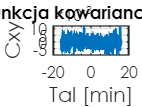

[f_cov, lags] = xcov(V, HR, 'unbiased',N/2);
tal=lags*dt;
figure; plot(tal, f_cov, 'LineWidth', 2); 
my_figure('Tal [min]', 'Cxy', 'Funkcja kowariancji V-HR');
grid on;

**Współczynnik kowariancji na podstawie funkcji kowariancji**

współczynni kowariancji dla zerowego przesunięcia

(na osi x jest przesunięcie sygnałów- przesunięcie 0 wypada dla współczynnika kowariancji)

wsp_f_cov = f_cov(tal==0)

wsp_f_cov = 0.0027

We współczynniku czy w funkcji kowariancji brakuje normowania- jeśli będziemy badać inne pary sygnałów, otrzymamy inny współczynnik oraz funkcję kowariancji, ciężko będzie je porównywać nie mając miary odniesienia. Dlatego też potrzebne jest normowanie. 

#### Współczynnik KORELACJI


$$\rho \left\lbrack x\left(t\right),y\left(t\right)\right\rbrack =\frac{\textrm{cov}\left(\left\lbrack x\left(t\right),y\left(t\right)\right\rbrack \right.}{\sigma_x \sigma_y }$$


współczyynik korelacji- jest to współczynnik kowariancji podzielony przez odchylenie standardowe badanych sygnałów x i y

przyjmuje wartości rzeczywiste z zakresu [-1 1], ujemna wartość- ujemna korelacja, dodatnia wartość- dodatnia korelacja, 0- brak korelacji

Wariancje na głównej przekątnej są unormowane i przyjmują wartość 1

 %% 1 - Analitycznie przez normowanie współczynnika kowariancji
varV = var(V);
varHR = var(HR);
stdV = std(V);
stdHR = std(HR);
 
wsp_kor1_1 = m_cov(1,1) / varV

wsp_kor1_1 = 1.0000

wsp_kor1_2 = m_cov(1,2) / (stdV * stdHR)

wsp_kor1_2 = 0.0335

wsp_kor2_2 = m_cov(2,2) / varHR

wsp_kor2_2 = 1.0000

 
m_kor_cov = [wsp_kor1_1 wsp_kor1_2; wsp_kor1_2 wsp_kor2_2]

m_kor_cov =     1.0000    0.0335
    0.0335    1.0000


%% Funkcja MATLABa
m_kor = corrcoef(V, HR)

m_kor =     1.0000    0.0335
    0.0335    1.0000


#### Funkcja korelacji:


$$R_{\textrm{xy}} \left(\tau \right)=\lim_{T\longrightarrow \infty } \frac{1}{T}\int_0^T x\left(t\right)\cdot y\left(t+\tau \right)\cdot \textrm{dt}$$


przyjmuje wartości rzeczywiste, brak jest normowania; problem z nazewnicwtem; 

%% Funkcja korelacji
 
%% 1 - Bezpośrednie wywołanie funkcji xcorr
[f_kor_raw, lags] = xcorr(V, HR, 'unbiased', N/2);
figure; subplot(211);
plot(tal, f_kor_raw, 'LineWidth', 2);
my_figure('Tal [min]', 'Rxy raw', 'Funkcja korelacji V-HR');
 
 

#### Unormowana funkcja korelacji


$$\rho_{\textrm{xy}} \left(\tau \right)=\frac{\lim_{T\longrightarrow \infty } \frac{1}{T}\int_0^T \left\lbrack x\left(t\right)-\mu_x \right\rbrack \cdot \left\lbrack y\left(t\right)-\mu_y \right\rbrack \cdot \textrm{dt}}{\sigma_x \sigma_y }$$


Dodatkowo odejmowane są wartości średnie- funkcja kowariancji podzielona przez odchylenie standardowe. Otrzymujemy unormowany sygnał, który jest z zakresu od -1 do 1. Wywoływana jest funkcja xcorr, od zmiennych odjęte są wartości średnie i unormowane (podzielone przez odchylenie prze parametr 'coef').

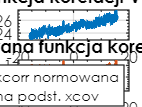

%% 2 - xcorr z odjętymi wartościami średnimi i unormowana
[f_kor_norm, lags] = xcorr(V - mean(V), HR - mean(HR), 'coef', N/2);
tal=lags*dt;
subplot(212)
plot(tal, f_kor_norm, 'LineWidth', 2); 
my_figure('Tal [min]', 'Rxy', 'Unormowana funkcja korelacji V-HR');
grid on;
 
 %% 3 - na podstawie funkcji kowariancji
f_kor_cov = f_cov / (stdV * stdHR);
 hold on;
plot(tal, f_kor_cov, 'LineWidth', 2); 
my_figure('Tal [min]', 'Rxy', 'Unormowana funkcja korelacji V-HR');
grid on; legend('xcorr normowana', 'na podst. xcov')

 
 
%% Współczynnik korelacji na podstawie funkcji korelacji
wsp_f_kor = f_kor_norm(tal==0)

wsp_f_kor = 0.0335

#### WNIOSKI KOŃCOWE

Jeżeli wartości jednego sygnału rosną, a drugiego malaję to mamy doczynienia z ujemną korelacją, jeśli oba sygnały rosną mamy dodatnią korelację. Kształt korelacji daje nam także dodatkowe informacje. Maksimum unormowanje funkcji korelacji jest przesunięte o około -0.5 i nie wypada dla zerowej wartości. Co oznacza, że jest opóźnienie między sygnałami. Funkcja jest okresowa, co oznacza, że sygnały się na siebie nakładają. 

Wygenerowanie dwóch sygnałów losowych, które są niezależne od siebie/ nie powiązane spowoduje, że sygnały nie będą okresowe. 

Na podstawie funkcji korelacji można wnioskować na teat okresowości sygnałów.

## Kowariancja a korelacja

[https://matlablog.ont.com.pl/matlab-i-zagadka-korelacji/](https://matlablog.ont.com.pl/matlab-i-zagadka-korelacji/)

**Badanie podobieństwa między sygnałami jest ważnym elementem wielu dziedzin nauki i techniki – nie tylko cyfrowego przetwarzania sygnałów. W tym wpisie zajmę się problemem ilościowego obliczania korelacji pomiędzy dwoma, a nawet wieloma sygnałami.**

Do problemu można podejść na wiele różnych sposobów. Teoria daje nam co najmniej kilka narzędzi do badania korelacji między sygnałami. Tak samo w MATLABie jest kilka funkcji do obliczeń numerycznych w tym zakresie. Można je podzielić ze względu na liczbę badanych sygnałów/zmiennych na:

- Współczynniki – czyli pojedyncze liczby, określające podobieństwo dwóch sygnałów,

- Macierze – zawierające tabele współczynników, a więc określające podobieństwo między wieloma sygnałami,

- Funkcje  - a więc wartości współczynników w funkcji przesunięcia dwóch sygnałów między sobą.

Jednak, żeby nie było zbyt łatwo, w literaturze znajdujemy informacje o tym, że wymienione powyżej miary podobieństwa występują w dwóch wariantach, jako:

- Kowariancja

- Korelacja

Należy podkreślić, że nomenklatura stosowana w literaturze nie jest tu spójna i również w MATLABie nie zawsze jest zgodna z ogólnie przyjętymi zasadami. Niemniej aby uporządkować wiedzę na ten temat musimy przyjąć, że:

**Kowariancja** – niezależnie od tego czy dotyczy macierzy czy funkcji jest wielkością nieunormowaną, to znaczy może ona przyjmować wartości z zakresu liczb rzeczywistych. Tym samym trudno porównać ze sobą dwa współczynniki kowariancji wyznaczone dla różnych sygnałów, gdyż otrzymana wartość zależy od wartości tych sygnałów. Kowariancja ma trzy charakterystyczne cechy:

- Jeżeli jest równa 0 to między badanymi sygnałami nie ma żadnego podobieństwa,

- Jeżeli jest dodatnia, to między sygnałami występuje „dodatnie” podobieństwo (np. sygnały we fazie),

- Jeżeli jest ujemna, to między sygnałami występuje „ujemne” podobieństwo (np. sygnały w przeciwfazie)

**Korelacja** – w przeciwieństwie do kowariancji, wartości korelacji są unormowane, najczęściej w taki sposób, że przyjmują one wartości z przedziału od -1 do 1. Dzięki temu, można z łatwością porównywać ze sobą tak unormowane liczby. Wartość 1 oznacza pełną korelację, czyli np. mamy do czynienia z dwoma identycznymi sygnałami. Wartość -1 oznacza pełną korelację ujemną, a 0 brak korelacji. Wartości pomiędzy -1 a 1 określają stopień podobieństwa.

Niektóre źródła literaturowe rozróżniają kowariancję i korelację w zależności od tego czy od badanych sygnałów odejmowane są ich wartości średnie przed policzeniem współczynników czy funkcji podobieństwa. I tak, jeżeli od sygnałów nie odejmujemy wartości średnich to mamy do czynienia z korelacją, a jeżeli odejmujemy to mamy do czynienia z kowariancją..

Jak widać można się w tym nieco pogubić.. W MATLABie nie ma spójności w tym zakresie. Współczynniki kowariancja/korelacja są rozróżniane ze względu na to czy są normowane do jedności czy nie. Natomiast funkcje kowariancji/korelacji są rozróżniane ze względu na to, czy od sygnałów są odejmowane ich wartości średnie czy nie. Na dodatek funkcje kowariancji/korelacji można dodatkowo w MATLABie normować do jedności…

Można się pogubić..

**MATLAB**

Mimo zawiłości nomenklatury patrząc na funkcje dostępne w MATLABie można wiedzę dodatkowo uporządkować. Do obliczania kowariancji są dostępne funkcje: cov – macierz kowariancji oraz xcov – funkcja kowariancji.

Do obliczania korelacji są funkcje: corrcoef – macierz korelacji oraz xcorr – funkcja korelacji.

Użycie funkcji cov – oblicza więc nieunormowaną macierz kowariancji, a użycie funkcji corrcoef normuje te obliczenia do jedności dzięki czemu otrzymujemy macierz korelacji.

Funkcja xcov – oblicza funkcje kowariancji z sygnałów z odjętą od nich wartością średnią, a funkcja xcorr oblicza funkcję korelacji czyli z sygnałów bez odejmowania od nich wartości średniej.

Dodatkowo funkcje xcov i xcorr mogą być normowane do jedności dla zerowego przesunięcia czasowego między sygnałami…

Uff.. trudno powiedzieć jaka logika stała za takim skonstruowaniem narzędzi do badania podobieństwa w MATLABie.. Muszę przyznać, że to jeden z bardziej zawiłych zakątków obliczeń numerycznych w pakiecie Mathworksa. Mam nadzieję, że przykłady, które umieszczę w następnym poście dodatkowo wyjaśnią sytuacje.